## Loading template models

clear;
% 
addpath('fieldtrip-20250106')
ft_defaults;

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re


freqRange = [0.5 100];

% ------------------------
% Load template models
% ------------------------

% The main trick is to keep in the same directory on the left as it reads from there 



% Load Head model
head_model_dir   = fullfile([cd,'/fieldtrip-20250106/template/headmodel']);
load(fullfile(head_model_dir, 'standard_singleshell.mat')); 
headmodel   = ft_convert_units(vol,'mm');

% Load Source Model
%source_model_dir = fullfile([cd,'\fieldtrip-20250106\template\Sourcemodel']);
load(fullfile('sourcemodelSample.mat'));

sourcemodel = ft_convert_units(sourcemodel,'mm');

% Load atlas for parcellation (optional)
cd


/MATLAB Drive/Day4/Day-4-17-Aug/lab



file = [cd,'\fieldtrip-20250106\template\atlas\aal\ROI_MNI_V4.nii']

file = '/MATLAB Drive/Day4/Day-4-17-Aug/lab\fieldtrip-20250106\template\atlas\aal\ROI_MNI_V4.nii'

atlas = ft_read_atlas([cd,'/fieldtrip-20250106/template/atlas/aal/ROI_MNI_V4.nii']);

the coordinate system appears to be 'aligned'
subselecting 116 labels from the total list of 116
re-indexing label Precentral_L to a value of 1 (was 2001)
re-indexing label Precentral_R to a value of 2 (was 2002)
re-indexing label Frontal_Sup_L to a value of 3 (was 2101)
re-indexing label Frontal_Sup_R to a value of 4 (was 2102)
re-indexing label Frontal_Sup_Orb_L to a value of 5 (was 2111)
re-indexing label Frontal_Sup_Orb_R to a value of 6 (was 2112)
re-indexing label Frontal_Mid_L to a value of 7 (was 2201)
re-indexing label Frontal_Mid_R to a value of 8 (was 2202)
re-indexing label Frontal_Mid_Orb_L to a value of 9 (was 2211)
re-indexing label Frontal_Mid_Orb_R to a value of 10 (was 2212)
re-indexing label Frontal_Inf_Oper_L to a value of 11 (was 2301)
re-indexing label Frontal_Inf_Oper_R to a value of 12 (was 2302)
re-indexing label Frontal_Inf_Tri_L to a value of 13 (was 2311)
re-indexing label Frontal_Inf_Tri_R to a value of 14 (was 2312)
re-indexing label Frontal_Inf_Orb_L to a

atlas = ft_convert_units(atlas,'mm');



 

## Loading MEG data


load('Sample_MEG_Data.mat') 

MEG = dataMAT; 
 

## Pre-processing data

cfg                = [];
cfg.channel        = 'all';
% cfg.continuous     = 'yes';
cfg.demean         = 'yes';
cfg.detrend        = 'yes';
cfg.dftfilter      = 'yes';
cfg.bpfilter       = 'yes';
cfg.dftfreq        = 50;
cfg.bpfreq         = freqRange;
Filt_MEG_Data      = ft_preprocessing(cfg,MEG);

 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/fixsampleinfo.m' at line 110
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_datatype_raw.m' at line 167
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 280
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_preprocessing.m' at line 276



 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/fixsampleinfo.m' at line 123
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_datatype_raw.m' at line 167
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 280
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_preprocessing.m' at line 276



 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 789
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 739
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_selectdata.m' at line 197
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_preprocessing.m' at line 319

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 2 MB
preprocessing
preprocessing trial 20 from 20
the call to "ft_preprocessing" took 2 seconds and required the additional allocation of an estimated 287 MB


## Compute Covarience

cfg            = [];
cfg.covariance = 'yes';
cfg.keeptrials = 'no';
timelock_RS    = ft_timelockanalysis(cfg,Filt_MEG_Data);

the input is raw data with 306 channels and 20 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_timelockanalysis" took 2 seconds and required the additional allocation of an estimated 329 MB


## sensor layout

reading layout from file neuromag306mag_helmet.mat
reading 'layout' from file 'neuromag306mag_helmet.mat'
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 2 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_topoplotER" took 1 seconds and required the additional allocation of an estimated 11 MB


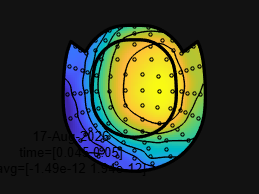

% Load sensor layout (you may need to adjust this to your system, e.g., CTF151, neuromag306, etc.)
%figure; plot(timelock_RS.time, timelock_RS.avg)


% ------------------------------------------------
% go into the Day_lab_graph.m to run
%
% press run and wait for a bit and press stop
% ------------------------------------------------

% view the results
cfg        = [];
cfg.layout = 'neuromag306mag_helmet.mat';
cfg.xlim   = [0.045 0.050];
ft_topoplotER(cfg, timelock_RS);

## Source analysis

cfg                 = [];
cfg.method          = 'lcmv';
cfg.rawtrial        = 'no';
cfg.sourcemodel     = sourcemodel;
cfg.headmodel       = headmodel;
cfg.lcmv.keepfilter = 'yes';
cfg.lcmv.fixedori   = 'yes';
cfg.grad            = timelock_RS.grad;
source              = ft_sourceanalysis(cfg, timelock_RS);

the input is timelock data with 306 channels and 7000 timebins
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
computing the leadfields on the fly
Your data and configuration allow for multiple sensor definitions.


converting units from 'cm' to 'mm'
computing surface normals
creating sourcemodel based on user specified dipole positions
using gradiometers specified in the configuration
181 dipoles inside, 629 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 0 seconds and required the additional allocation of an estimated 0 MB
scanning repetition 1
computing forward model on the fly
scanning grid
scanning grid 181/181
the call to "ft_sourceanalysis" took 2 seconds and required the additional allocation of an estimated 6 MB


## brain mapping

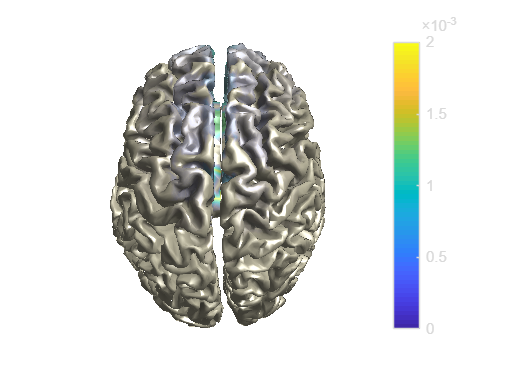

the input is source data with 810 brainordinates on a [9 10 9] grid
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 2 MB
not plotting anatomy
not using an atlas
not using a region-of-interest


The source functional is defined on a 3D grid, interpolation to a surface mesh will be performed
downsampling surface from 346499 vertices
810 voxels in functional data
34653 vertices in cortical surface
the input is mesh data with 34653 vertices and 69298 triangles
the input is parcellated source data with 34653 brainordinates
the input is source data with 810 brainordinates on a [9 10 9] grid


 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 789
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 739
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 1435
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 402
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_sourceinterpolate.m' at line 170
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_sourceplot.m' at line 1252



 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 789
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 739
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 1435
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 402
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_sourceinterpolate.m' at line 170
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_sourceplot.m' at line 1252



 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 789
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 739
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 1435
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 402
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_sourceinterpolate.m' at line 170
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_sourceplot.m' at line 1252



 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 789
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 739
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 1435
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 402
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_sourceinterpolate.m' at line 170
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_sourceplot.m' at line 1252



 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 789
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 739
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdatfield.m' at line 45
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_datatype_volume.m' at line 143
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 403
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_sourceinterpolate.m' at line 170
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_sourceplot.m' at line 1252

could not reshape "time" to the dimensions of the volume
interpolating pow
the call to "ft_sourceinterpolate" took 1 seconds and required the additional allocation of an estimated 7 MB
the call to "ft_sourceplot" took 24 seconds and required the additional allocation of an estimated 450 MB



% ------------------------------------------------
% go into the Day_lab_graph.m to run
% ------------------------------------------------


cfg = [];
cfg.method         = 'surface';
cfg.funparameter   = 'pow';
cfg.maskparameter  = cfg.funparameter;
cfg.funcolormap    = 'parula';
cfg.opacitymap     = 'rampup';
cfg.projmethod     = 'nearest';
cfg.surffile       = 'surface_white_both.mat';
cfg.surfdownsample = 10;

figure('WindowStyle','normal')
ft_sourceplot(cfg, source);

##  Parcellate the voxels to anatomical regions

% Interpolate atlas to sourcemodel space
cfg = [];
cfg.interpmethod = 'nearest';
cfg.parameter    = 'tissue';
cfg.atlas        = atlas;
cfg.inputcoord   = 'mni';
cfg.pos          = source.pos;
atlas_interp     = ft_sourceinterpolate(cfg, atlas, source);

the input is source data with 810 brainordinates on a [9 10 9] grid


 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 789
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 739
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 1435
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 402
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_sourceinterpolate.m' at line 164



 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 789
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 739
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 1435
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 402
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_sourceinterpolate.m' at line 164



 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 789
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 739
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 1435
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 402
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_sourceinterpolate.m' at line 164



 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 789
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 739
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 1435
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 402
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_sourceinterpolate.m' at line 164



 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 789
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdimord.m' at line 739
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/private/getdatfield.m' at line 45
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_datatype_volume.m' at line 143
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/utilities/ft_checkdata.m' at line 403
 In '/MATLAB Drive/Day4/Day-4-17-Aug/lab/fieldtrip-20250106/ft_sourceinterpolate.m' at line 164

could not reshape "time" to the dimensions of the volume
the input is segmented volume data with dimensions [91 109 91]
voxel size along 1st dimension (i) : 2.000000 mm
voxel size along 2nd dimension (j) : 2.000000 mm
voxel size along 3rd dimension (k) : 2.000000 mm
volume per voxel                   : 8.000000 mm^3
the volume of each of the segmented compartments in "tissue" is
Precentra


source_parcellated = struct();

% Loop through atlas regions
for r = 1:numel(atlas.tissuelabel)
    vox_idx = find(atlas_interp.tissue == r);
    if isempty(vox_idx), continue; end

    all_vox_ts = [];
    for v = 1:numel(vox_idx)
        vIdx = vox_idx(v);
        if ~isempty(source.avg.mom{vIdx})
            all_vox_ts(end+1,:) = source.avg.mom{vIdx};
        end
    end

    if isempty(all_vox_ts)
        continue;
    end

    reg_signal = mean(all_vox_ts,1);

    source_parcellated.(atlas.tissuelabel{r}) = reg_signal;
end

 